% Preparing data
data = 'LIDAR_data.mat';

total = LIDAR_Frame_Change(data);

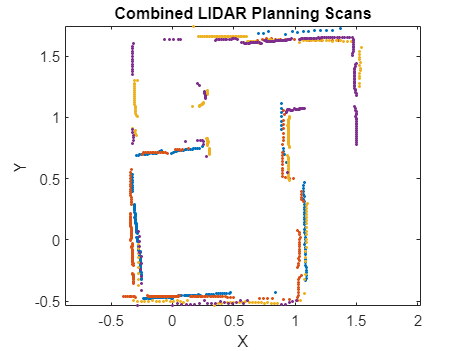

% Combining all coordinate points
total_coords = [];
for i=1:4
    coords = total{i};
    plot(coords(1,:), coords(2,:), ".");
    total_coords = [total_coords coords];
    hold on;
end
axis equal;
xlabel('X')
ylabel('Y')
title('Combined LIDAR Planning Scans')
hold off;

total_coords = total_coords';

    0.1071



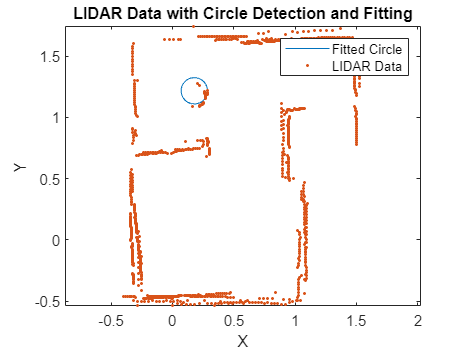

r_avg_best = 0.1071

x_c_best = 0.1786

y_c_best = 1.2159

detected = 1

% Running fitting algorithm
[r_avg_best, x_c_best, y_c_best, detected] = fit_circle(total_coords, 0.115, 3)

% Finding which points are on the circle
circle_coords = [];
for i = 1:size(total_coords, 1)
    distance_to_center = sqrt((total_coords(i, 1) - x_c_best)^2 + (total_coords(i, 2) - y_c_best)^2);
    
    % Check if the distance is within a certain threshold of the radius
    if abs(distance_to_center - r_avg_best) <= 0.075
        circle_coords = [circle_coords; total_coords(i, :)];
    end
end

% Find the indices of points that are close to the fitted circle
indices_to_remove = [];
for i = 1:size(total_coords, 1)
    distance_to_center = sqrt((total_coords(i, 1) - x_c_best)^2 + (total_coords(i, 2) - y_c_best)^2);
    if abs(distance_to_center - r_avg_best) <= 0.1
        indices_to_remove = [indices_to_remove; i];
    end
end

% Remove the points from total_coords
total_coords(indices_to_remove, :) = [];

dim = 100

dim = 100

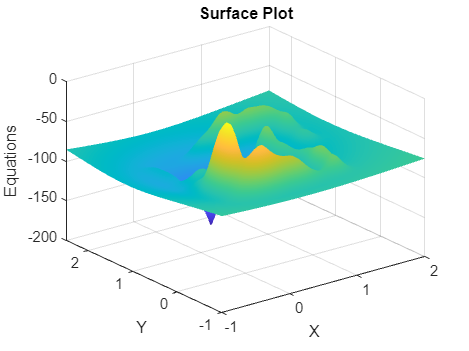


% Defining plot space
[X, Y] = meshgrid(linspace(-1, 2, 100), linspace(-1, 2.5, 100));

% Initialize equations with a high value
equations = ones(size(X)) * -100;

% Define the parameters of the Gaussian function
amplitude = 5;  % Amplitude of the Gaussian
sigma = 0.1;    % Standard deviation, determines the width of the Gaussian

% Creating source equations
for i = 1:5:size(total_coords, 1)
    equations = equations + amplitude * exp(-((X - total_coords(i,1)).^2 + (Y - total_coords(i,2)).^2) / (2 * sigma^2));
end


% Adding sink equations
for i = 1:size(circle_coords, 1)
    equations = equations + 1 * log(sqrt((X - circle_coords(i,1)).^2 + (Y - circle_coords(i,2)).^2));
end

surf(X, Y, equations);
xlabel('X');
ylabel('Y');
zlabel('Equations');
title('Surface Plot');
shading interp;

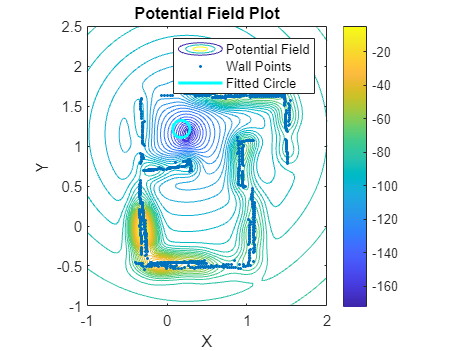


contour(X, Y, equations, 40);
hold on;
plot(total_coords(:,1), total_coords(:,2), ".")
th = 0:pi/50:2*pi;
xunit = r_avg_best * cos(th) + x_c_best;
yunit = r_avg_best * sin(th) + y_c_best;
plot(xunit, yunit, 'color', 'cyan', 'LineWidth', 2);
xlabel('X');
ylabel('Y');
title('Potential Field Plot')
legend('Potential Field', 'Wall Points', 'Fitted Circle', 'location', 'northeast');
axis equal;
colorbar('eastoutside');
hold off;

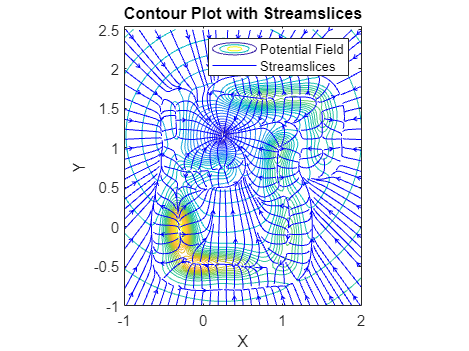


[Gx, Gy] = gradient(equations);

contour(X, Y, equations, 40);
hold on;
streamslice(X, Y, -1 * Gx, -1 * Gy, 2);
% plot(total_coords(:,1), total_coords(:,2), ".");
xlabel('X');
ylabel('Y');
title('Contour Plot with Streamslices');
legend('Potential Field', 'Streamslices')
axis equal;
hold off;

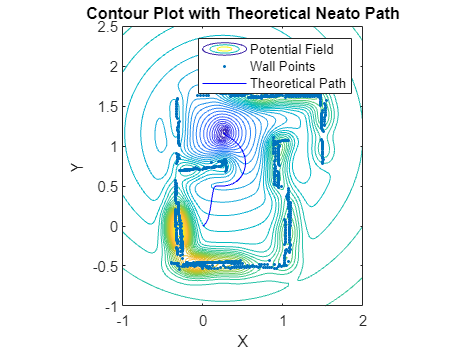


contour(X, Y, equations, 40);
hold on;
plot(total_coords(:,1), total_coords(:,2), ".");
streamline(X, Y, -1 * Gx, -1 * Gy, 0, 0);
xlabel('X');
ylabel('Y');
title('Contour Plot with Theoretical Neato Path');
legend('Potential Field', 'Wall Points', 'Theoretical Path')
axis equal;
hold off;

dim = 100

dim = 100

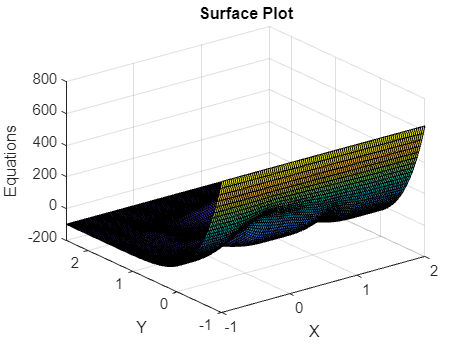


% Defining plot space
[X, Y] = meshgrid(linspace(-1, 2, 100), linspace(-1, 2.5, 100));

% Initialize equations with a high value
equations = ones(size(X)) * -100;

% Define the parameters of the Gaussian function
amplitude = 5;  % Amplitude of the Gaussian
sigma = 0.15;    % Standard deviation, determines the width of the Gaussian

% Creating source equations
for i = 1:5:size(total_coords, 1)
    equations = equations + amplitude * exp(-((X - total_coords(i,1)).^2 + (Y - total_coords(i,2)).^2) / (2 * sigma^2));
end

equations = equations + (Y - 2).^6;

[Gx, Gy] = gradient(equations);

surf(X, Y, equations);
xlabel('X');
ylabel('Y');
zlabel('Equations');
title('Surface Plot');

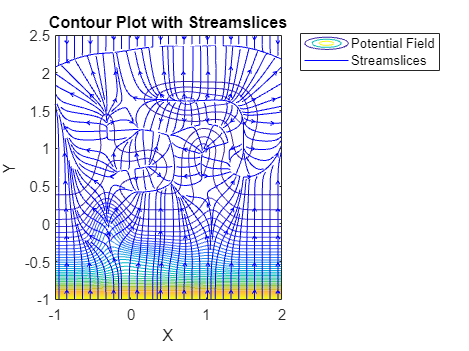


contour(X, Y, equations, 40);
hold on;
streamslice(X, Y, -1 * Gx, -1 * Gy, 2);
% plot(total_coords(:,1), total_coords(:,2), ".");
xlabel('X');
ylabel('Y');
title('Contour Plot with Streamslices');
legend('Potential Field', 'Streamslices')
axis equal;
hold off;

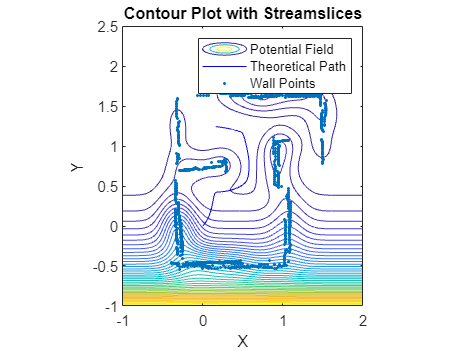


contour(X, Y, equations, 40);
hold on;
streamline(X, Y, -1 * Gx, -1 * Gy, 0, 0);
plot(total_coords(:,1), total_coords(:,2), ".");
xlabel('X');
ylabel('Y');
title('Contour Plot with Streamslices');
legend('Potential Field', 'Theoretical Path', 'Wall Points')
axis equal;
hold off;